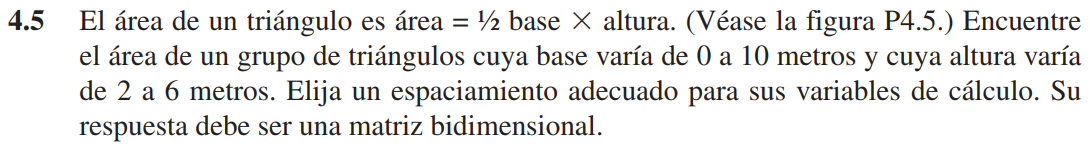

clear

% Definir lo que se conoce.
b = 0:2:10;
h = 2:6;

% Determinar la relación entre las variables.
[new_b, new_h] = meshgrid(b,h);

% Aplicar la ecuación para determinar el área.
A = .5*new_b.*new_h     % Área para cada base y altura.

A =      0     2     4     6     8    10
     0     3     6     9    12    15
     0     4     8    12    16    20
     0     5    10    15    20    25
     0     6    12    18    24    30


                        % Base en las columnas, altura en las filas.

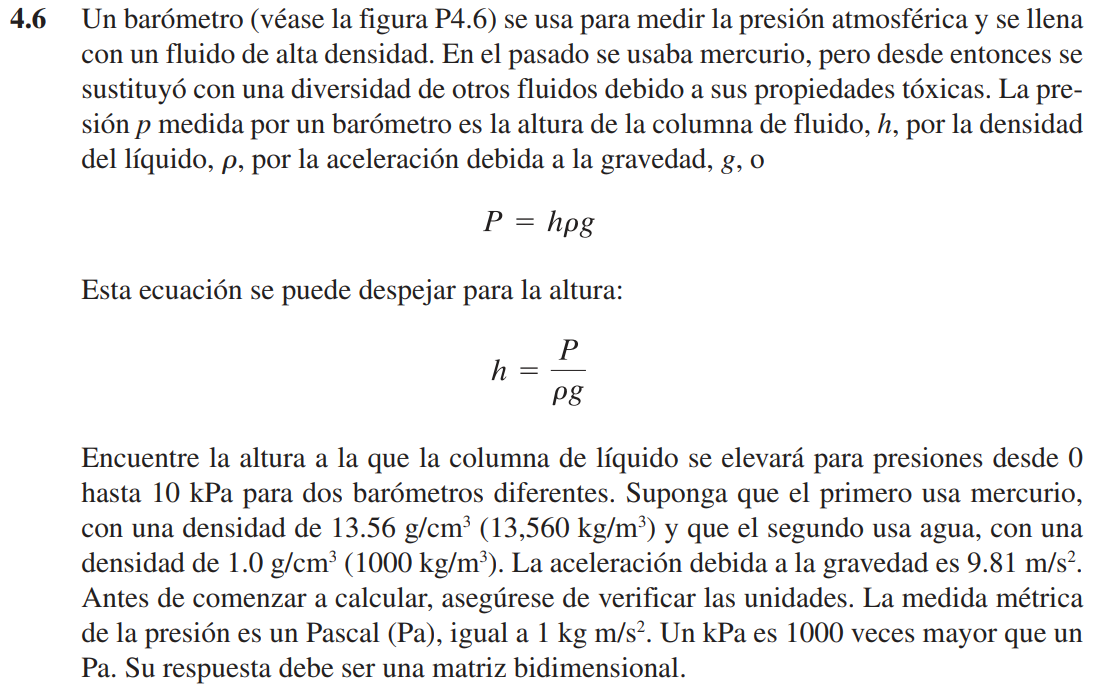

Trabajando con las unidades planteadas en el ejercicio, el factor de conversión que se aplicará al final, para determinar `h`, es $10^5$. Esto nos dará los valores de `h` en cm.

**Nota:** Lo que se hizo fue trabajar las unidades únicamente, sin embargo, se recomienda realizarlo para entender si se tiene dudas.

clear

% Definimos lo que se conoce.
g = 9.81;               % Gravedad en m/s^2.
P = 0:2:10;             % Presión en kPa.
d = [13560 1000];       % Densidad en km/m^3.

% Determinar la relación entre las variables.
[new_P, new_d] = meshgrid(P,1./d);

% Aplicar la ecuación para determinar la altura en cm.
h = [1e5/g*new_P.*new_d]'   % Densidad en las columnas, presión en las filas.

h =          0         0
    1.5035   20.3874
    3.0070   40.7747
    4.5105   61.1621
    6.0140   81.5494
    7.5175  101.9368
